# Geoneutrino Flux Measurements

This code takes into account the uncertainties on both the x- and y-axis. Currently there are only 2 datapoints, KamLAND and Borexino, with plans to add more as they become available. The y-intercept is the TNU signal coming from the non-lithospheric mantle. The slope of the fit line is fixed at 1.

### Enter the total geoneutrino signal (i.e., physics measurement, y-axis on graph) in TNU.

Kamland_T = 31; ktplus = 5; ktminus = 5;
Borexino_T = 47; btplus = 10.8; btminus = 9.6;
Extra_detector_T = 35; etplus = 8; etminus = 7;


### Enter the lithospheric geoneutrino signal (i.e., geology prediction, x-axis on graph) in TNU.

Kamland_L = 24.8; klplus = 6.7; klminus = 5.3;
Borexino_L = 34.2; blplus = 8; blminus = 6.5;
Extra_detector_L = 28; elplus = 6; elminus = 5;


xdata = [Kamland_L Borexino_L Extra_detector_L];% Sno_L]; % lithosphere
ydata = [Kamland_T Borexino_T Extra_detector_T];% Sno_T]; % total

kaml_unc = (klplus + klminus)./Kamland_L;
kamt_unc = (ktplus + ktminus)./Kamland_T;
kam_unc = sqrt(kaml_unc.^2 + kamt_unc.^2);

bxl_unc = (blplus + blminus)./Borexino_L;
bxt_unc = (btplus + btminus)./Borexino_T;
bx_unc = sqrt(bxl_unc.^2 + bxt_unc.^2);

exdl_unc= (elplus + elminus)./Extra_detector_L;
exdt_unc = (etplus + etminus)./Extra_detector_T;
exd_unc = sqrt(exdl_unc.^2 + exdt_unc.^2);


% weights = sqrt of relative x and y uncertainty squared
weights = [kam_unc bx_unc exd_unc]./(kam_unc);

[fitresult1, gof1] = createFit(xdata,ydata,weights);

y-intercept is 8.44 TNU. Laura is tired and has not written the +/- to appear in this output yet.


yint_unc_percent = sqrt(kam_unc.^2 + bx_unc.^2 + exd_unc.^2).*100

yint_unc_percent = 102.1934

To convert from mantle TNU to radiogenic power in the bulk silicate Earth (from U, Th, and K), you need to do calculations which are not explained in Sramek et al 2016 or Wipperfurth et al 2020. From a visual inspection of the points on the graph for their conversion, you multiply the y-intercept TNU by 1.111 and then add the lithosphere's radiogenic power,

y1 = [6 15]; %visually estimated from sra 2016
y2 = [11 25];  %visually estimated from sra 2016
m = (25-15)./(15-6);


mantleTW = fitresult1.p2.*1.111; % the ACTUAL math for this conversion needs to be written out and explained. Neither Sramek 2016 nor Wipp 2020 do this.

BSE_radiogenic = 8.2 + mantleTW;

disp(['which is roughly ', num2str(BSE_radiogenic),' TW of radiogenic power in the BSE.']) % numbers not finalized 

which is roughly 17.5759 TW of radiogenic power in the BSE.


% until KamLAND new numbers in and specific lithosphere TW is used.
mytitle = "My Title";
title(mytitle)


hold on
yneg = [ktminus btminus etminus];
ypos = [ktplus btplus etplus];

xneg = [klminus blminus elminus];
xpos = [klplus blplus elplus];

errorbar(xdata,ydata,yneg,ypos,xneg,xpos,'o');
hold off
legend off

Adjust these sliders to change the max x- and y- limits on the graph

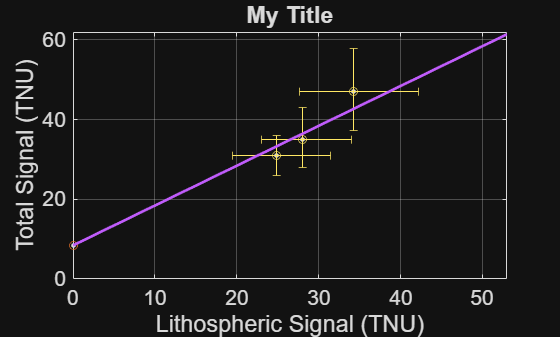

ymax = 62;
xmax = 53;
line([0 xmax],[fitresult1.p2 fitresult1.p2+xmax])


 


xlim([0 xmax])
ylim([0 ymax])

% 
% [fit2, gof2] = createFit([Kamland_L-klminus Borexino_L-blminus],[Kamland_T+ktplus Borexino_T+btplus],[1 1]);
% fit2.p2
% 
% [fit3, gof3] = createFit([Kamland_L+klplus Borexino_L+blplus],[Kamland_T-ktminus Borexino_T-btminus],[1 1]);
% fit3.p2

function [fitresult, gof] = createFit(xdata, ydata, weights)
%CREATEFIT(XDATA,YDATA,WEIGHTS)
%  Create a fit.
%
%  Data for '1:1 Line' fit:
%      X Input: xdata
%      Y Output: ydata
%      Weights: weights
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 03-Jul-2024 00:49:01


%% Fit: '1:1 Line'.


[xData, yData, weights_1] = prepareCurveData( xdata, ydata, weights );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Lower = [1 0];
opts.Upper = [1 Inf];
opts.Weights = weights_1;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
    figure( 'Name', '1:1 Line' );
    h = plot( fitresult, [xData; 0], [yData; fitresult.p2]);
    hold on
    scatter(0,fitresult.p2)

    legend( 'Detectors', '1:1 Line', 'y-intercept', 'Location','northwest');
    % Label axes
    xlabel( 'xdata', 'Interpreter', 'none' );
    ylabel( 'ydata', 'Interpreter', 'none' );
    grid on
    set(gca,'fontsize',16)
    xlabel('Lithospheric Signal (TNU)')
    ylabel('Total Signal (TNU)')

    xlim([0 max(xData+5)])

    disp(['y-intercept is ', num2str(round(fitresult.p2,2)), ' TNU. Laura is tired and has not written the +/- to appear in this output yet.'])
end